% syms s t;
s = tf('s');
student_num = [3 8 1 1 3 5 4 4];


P2_ampDataPlot(38113544);

Unrecognized function or variable 'P2_ampData'.

Error in P2_ampDataPlot

T_r   = 20; %ms
T_p   = 30; 
T_s   = 75;


final_value = 14;
overshoot   = 16.5-final_value;
p_overshoot = overshoot/final_value*100;

zeta = sqrt(log(overshoot/final_value)^2/(pi^2+log(overshoot/final_value)^2));
beta = sqrt(1-zeta^2);
% beta_2 = -3*pi/log(p_overshoot)



% we want to find the zeta and the natural frequency so we can then
% approximate this curve as the step response of a 2nd order system

wn_ts = 4/(zeta*T_s);

wn_tp = pi/(T_p*beta);

wn_tr = (pi-atan(beta/zeta))/(beta*T_r);

xfer_s = 1/s*wn_ts^2/(s^2+2*zeta*wn_ts*s+wn_ts^2)*final_value;
xfer_p = 1/s*wn_tp^2/(s^2+2*zeta*wn_tp*s+wn_tp^2)*final_value;
xfer_r = 1/s*wn_tr^2/(s^2+2*zeta*wn_tr*s+wn_tr^2)*final_value;

figure(1);
set(findall(gcf,'type','line'),'Color','green');

[y_s, t_s] = impulse(xfer_s)

y_s =          0
    0.2410
    0.9012
    1.8879
    3.1133
    4.4963
    5.9641
    7.4534
    8.9109
   10.2932


t_s =          0
    1.7269
    3.4539
    5.1808
    6.9078
    8.6347
   10.3616
   12.0886
   13.8155
   15.5424


[y_p, t_p] = impulse(xfer_p)

y_p =          0
    0.2410
    0.9012
    1.8879
    3.1133
    4.4963
    5.9641
    7.4534
    8.9109
   10.2932


t_p =          0
    1.6039
    3.2077
    4.8116
    6.4155
    8.0194
    9.6232
   11.2271
   12.8310
   14.4349


[y_r, t_r] = impulse(xfer_r)

y_r =          0
    0.2410
    0.9012
    1.8879
    3.1133
    4.4963
    5.9641
    7.4534
    8.9109
   10.2932


t_r =          0
    1.6209
    3.2418
    4.8627
    6.4836
    8.1045
    9.7254
   11.3463
   12.9672
   14.5881


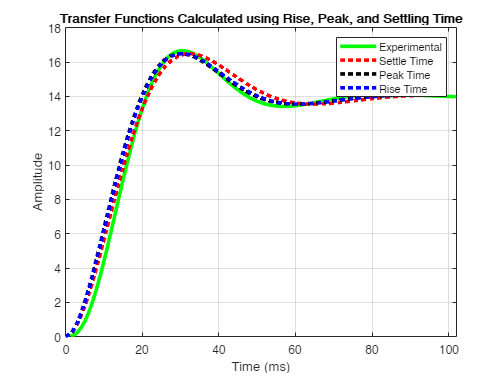


hold on
plot(t_s, y_s, ':', 'LineWidth', 3, 'Color','Red')
plot(t_p, y_p, ':', 'LineWidth', 3, 'Color','Black')
plot(t_r, y_r, ':', 'LineWidth', 3, 'Color','Blue')
grid on
hold off

title("Transfer Functions Calculated using Rise, Peak, and Settling Time")
xlabel("Time (ms)")
ylabel("Amplitude")
axis([0, 102, 0, 18])
legend("Experimental", "Settle Time", "Peak Time", "Rise Time")

T_s_n = 66.5;
overshoot_n = 16.6647-final_value;
p_overshoot_n = overshoot_n/final_value * 100;
zeta_n = sqrt(log(overshoot_n/final_value)^2/(pi^2+log(overshoot_n/final_value)^2));
beta_n = sqrt(1-zeta_n^2);
wn_ts_n = 4/(zeta_n*T_s_n);
xfer_s_n = 1/s*wn_ts_n^2/(s^2+2*zeta_n*wn_ts_n*s+wn_ts_n^2)*final_value;

[p,x] = pzmap(xfer_s_n)

p =    0.0000 + 0.0000i
  -0.0602 + 0.1139i
  -0.0602 - 0.1139i



x =

  0×1 empty double column vector



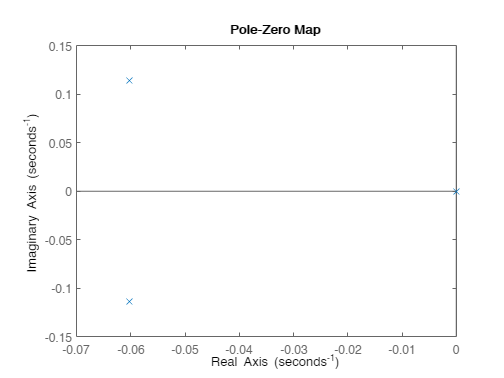

pzmap(xfer_s_n)